Practical Problem 12

Write a function file to obtain first derivative estimates for unequally spaced data. You may use any Matlab built-in functions. Test it with the following data:

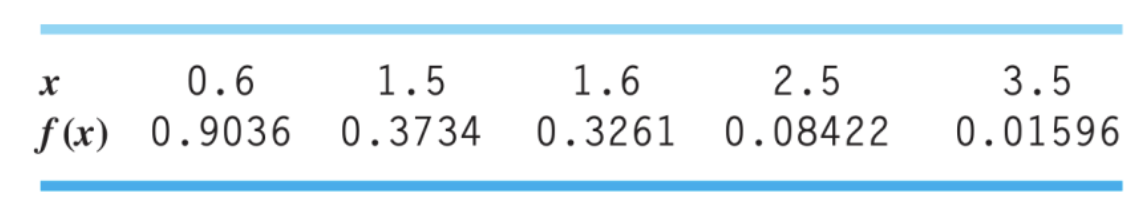

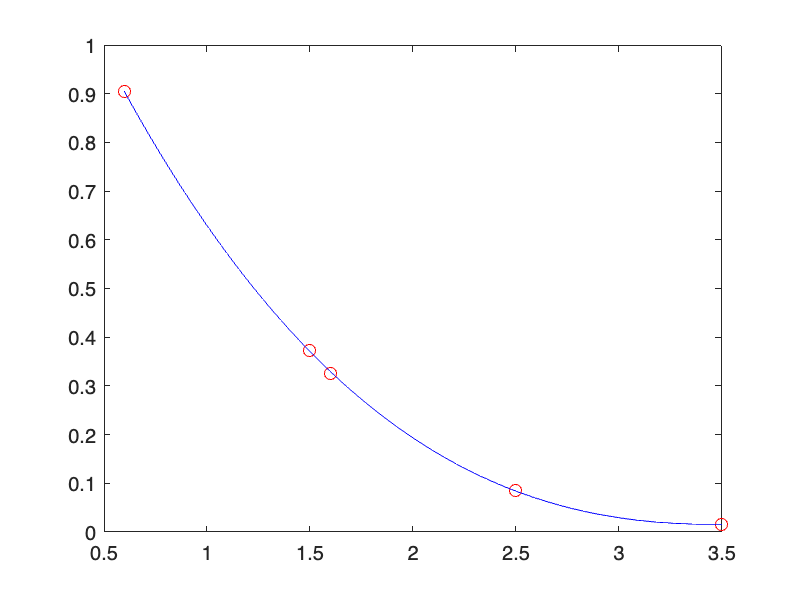

% Step 1: Data
x = [0.6 1.5 1.6 2.5 3.5];
y = [0.9036 0.3734 0.3261 0.08422 0.01596];

% Step 2: Fit to be 3rd Order Polynomial
p = polyfit(x, y, 3);
xx = linspace(min(x), max(x));
yy = polyval(p, xx);
plot(x, y, 'ro', xx, yy, 'b-');


% Step 3: Derivetive
dp = polyder(p);  % polyder Differentiate polynomial.
df = polyval(dp, x);

disp(p);

   -0.0178    0.2426   -1.0394    1.4438



disp('The derivative is:')

The derivative is:


disp(dp);

   -0.0533    0.4851   -1.0394



disp('The values of the derivatives at each x are:')

The values of the derivatives at each x are:


disp(df);

   -0.7675   -0.4316   -0.3996   -0.1595    0.0059



Use the following data to find the velocity and acceleration at t = 10 seconds using second order (a) centred finite difference, (b) forward finite difference, and (c) backward finite difference methods.

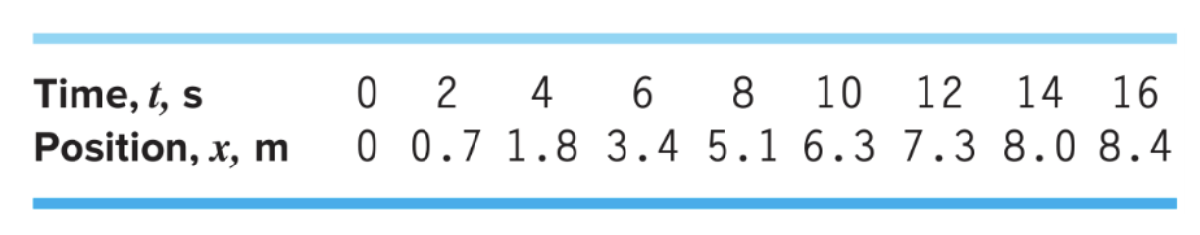

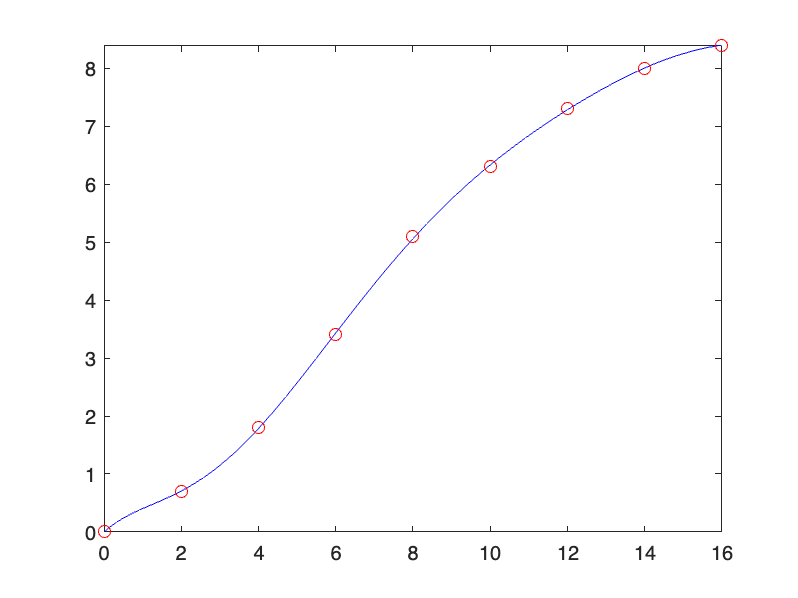

% Step 1: Data
t = [0 2 4 6 8 10 12 14 16];
s = [0 0.7 1.8 3.4 5.1 6.3 7.3 8 8.4];
p = polyfit(t, s, 7);
fplot(@(t) polyval(p, t), [0 16], 'b-');
hold on
plot(t, s, 'ro');


% Step 2: Centered Finite Differece @t = 10 | Reminder: ดิฟระยะทางได้ v ดิฟ v ได้ a
% cd = f(xi+1) - f(xi-1) / 2h + O(h.^2) | Slides 23
v_cd = (7.3 - 5.1) / 4;
v_cd2 = (-8 + 8*7.3 - 8*5.1 + 3.4) / 24;
fprintf('Standard CFD of v = %f and Improve CFD of v = %f\n', v_cd, v_cd2);

Standard CFD of v = 0.550000 and Improve CFD of v = 0.541667



% Step 3: Forward Finite Differnce
v_fd = (7.3 - 6.3) / 2;
v_fd2 = (-8 + 4*7.3 - 3*6.3) / 4;
fprintf('Standard FFD of v = %f and Improve FFD of v = %f\n', v_fd, v_fd2);

Standard FFD of v = 0.500000 and Improve FFD of v = 0.575000



% Step 4: Backward Finite Difference
v_bd = (6.3 - 5.1) / 2;
v_bd2 = (3*6.3 - 4*5.1 + 3.4) / 4;
fprintf('Standard BFD of v = %f and Improve FFD of v = %f\n', v_bd, v_bd2);

Standard BFD of v = 0.600000 and Improve FFD of v = 0.475000



% Step 5: Centered Finite Difference Finding Acceleration
a_cd = ( 7.3 - 2*6.3 + 5.1 ) / 4;
a_cd2 = ( -8 + 16*7.3 - 30*6.3 + 16*5.1 - 3.4 ) / 12*(2^2);

The following data were collected for the distance travelled versus time for a rocket. Use finite difference approximations to estimate the rocket’s velocity at each time using both standard and improved formulas.

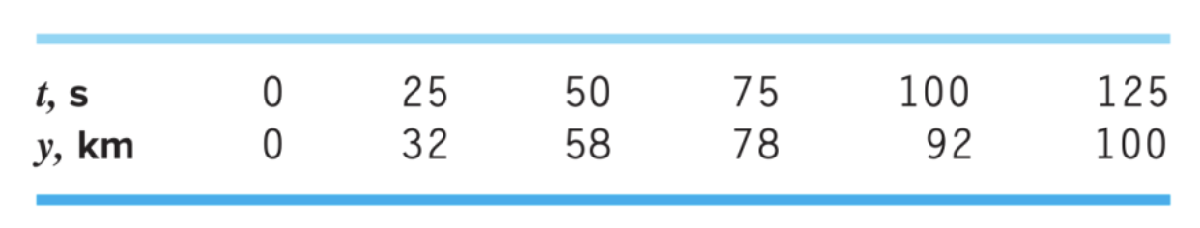

% Practical Problems 12 Question 3

% Step 1: Data
t = [0 25 50 75 100 125];
y = [0 32 58 78 92 100];

% Step 2: Finding velocity
v_fd = (32 - 0) / 25;
v_bd = (100-92) / 25;
v_cd = (y(3:6) - y(1:4)) ./ 50;

v_std = [v_fd v_cd v_bd];
disp(v_std);

    1.2800    1.1600    0.9200    0.6800    0.4400    0.3200




% Step 3: Improved
vi_fd = (-58 + 4*32 - 3*0) / 50;
vi_fd2 = (-78 + 4*58 - 3*32) / 50;
vi_bd = (3*100 - 4*92 + 78) / 50;
vi_bd2 = (3*92 - 4*78 + 58) / 50;
vi_cd = (-y(5:6) + (8.* y(4:5)) - (8.*y(2:3)) + y(1:2)) ./ (12*25) ;

vi_std = [vi_fd vi_fd2 vi_cd vi_bd2 vi_bd];
disp(vi_std);

    1.4000    1.1600    0.9200    0.6800    0.4400    0.2000



The velocity (m/s) of an object at time t seconds is given by the following function. Using one level of Richardson’s extrapolation, find the acceleration of the particle at time t = 5 s initially using h = 0.5 and 0.25. Use the exact solution to compute the true percent relative error of each estimate.

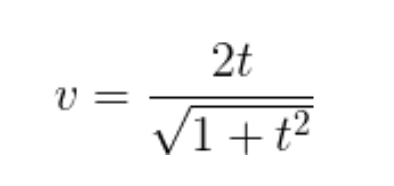

%% Practical Problems 12 Question 5

% Step 1: Setup Function
v = @(t) 2.*t ./ sqrt(1 + t.^2);
p = 5;

% Calculate difference approximation | Slides 19
D_worse = (v(p + 0.5) - v(p)) / 0.5;
D_better = (v(p+0.25)-v(p)) / 0.25;
% Use Richardson Extrapolation
D_improved = (4*D_better-D_worse) / 3;  % Slide 27

% Step 2: Get exact solution to calculate error
syms t
vv =(2*t)/sqrt(1+t^2);
dv = diff(vv);
dv= matlabFunction(dv);
D_actual = dv(p);

err_worse = abs((D_actual - D_worse) / D_actual)*100;
err_better = abs((D_actual - D_better) / D_actual)*100;
err_improved = abs((D_actual-D_improved) / D_actual)*100;

disp(D_worse);

    0.0132



disp(D_better);

    0.0141



disp(D_improved);

    0.0144



disp(err_worse);

   12.7863



disp(err_better);

    6.7794



disp(err_improved);

    4.7771



Evaluate ∂f/∂x, ∂f/∂y and ∂2f/∂x2 for the following function at x = y = 1 numerically 

with Δx = Δy = 0.0001

%% Practical Problems 12 Question 6

% Step 1: Create function
func = @(x, y) 3.*x.*y + 3.*x - x.^3 - 3.*(y.^2);
x = 1;
y = 1;
delX = 0.0001;
delY = 0.0001;

% Step 2: LET'S DO PARTIAL FUCKING DERIVERTIVE AND END THIS SHIT
fx = ( func(x + delX, y) - func(x - delX, y) ) ./ (2.*delX);
fy = ( func(x, y + delY) - func(x, y - delY) ) ./ (2.*delY);


fxx = ( ( func(x+delX, y) - 2*func(x,y) + func(x-delX,y) ) ) ./ (delX.^2);

disp(fx);

    3.0000



disp(fy);

   -3.0000



disp(fxx);

   -6.0000

